# 03 Line Search Methods

Each iteration of a line search method is of the form 


$$x_{k+1} =  x_k + \alpha _k p_k$$


- Given a point $x_k$, find a descent direction $p_k$.

- Find the step length $\alpha$ to minimize $f (x_k+\alpha p_k)$.

A **descent direction** $p_k$ means the directional derivative $\nabla f (x_k)^Tp_k < 0$.

In a **Newton-Type** methods, we have $p_k= - B^{-1}\nabla f(x_k)$, where $B$ is an $n\times n$ symmetric invertible matrix.

- Steepest descent: $B=I$.

- Newton's method: $B=H=\nabla^2 f(x_k)$is the Hessian.

- If $H$ is positive definite, $\nabla f(x_k) p_k< 0$.

***GOAL: ***  How to choose $\alpha _k$ and $p_k$ to promote **convergence** from remote starting points.

## 3.1 STEP LENGTH $\alpha$

- Assume $p_k$ is a descent direction. 

- Find an optimal step length $\alpha $.   This means solving an optimization problem:     $\min_{\alpha >0} \phi(\alpha ) = f(x_k + \alpha p_k)$

- **Exact line search ☹**: The minimization problem may be difficult to solve. (nonlinear) 

                                    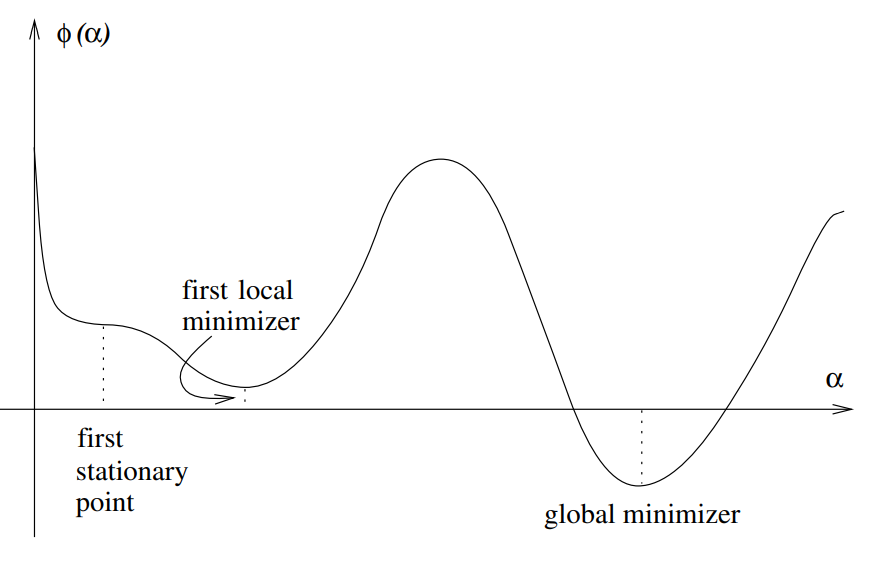

- **Inexact line search 🙂**: Alternative method is to find an $\alpha $ that satisfies some conditions:   - Wolfe conditions  - Goldstein conditions

####     THE WOLFE CONDITIONS

- **Sufficient decrease condition:** for $c_1\in (0,1)$,   $f(x_k + \alpha p_k) \le  f(x_k) + c_1\alpha \nabla f(x_k)^T p_k$         (*Armijo condition*)  In practice: $c_1=10^{-4}$.

- **Curvature condition:** for $c_2\in (c_1,1)$,  $\nabla f(x_k + \alpha p_k)^T p_k \ge  c_2\nabla f(x_k)^T p_k$

- Usually choose $c_2=0.9$ for Newton’s method and $c_2=0.1$ for conjugate gradient method 

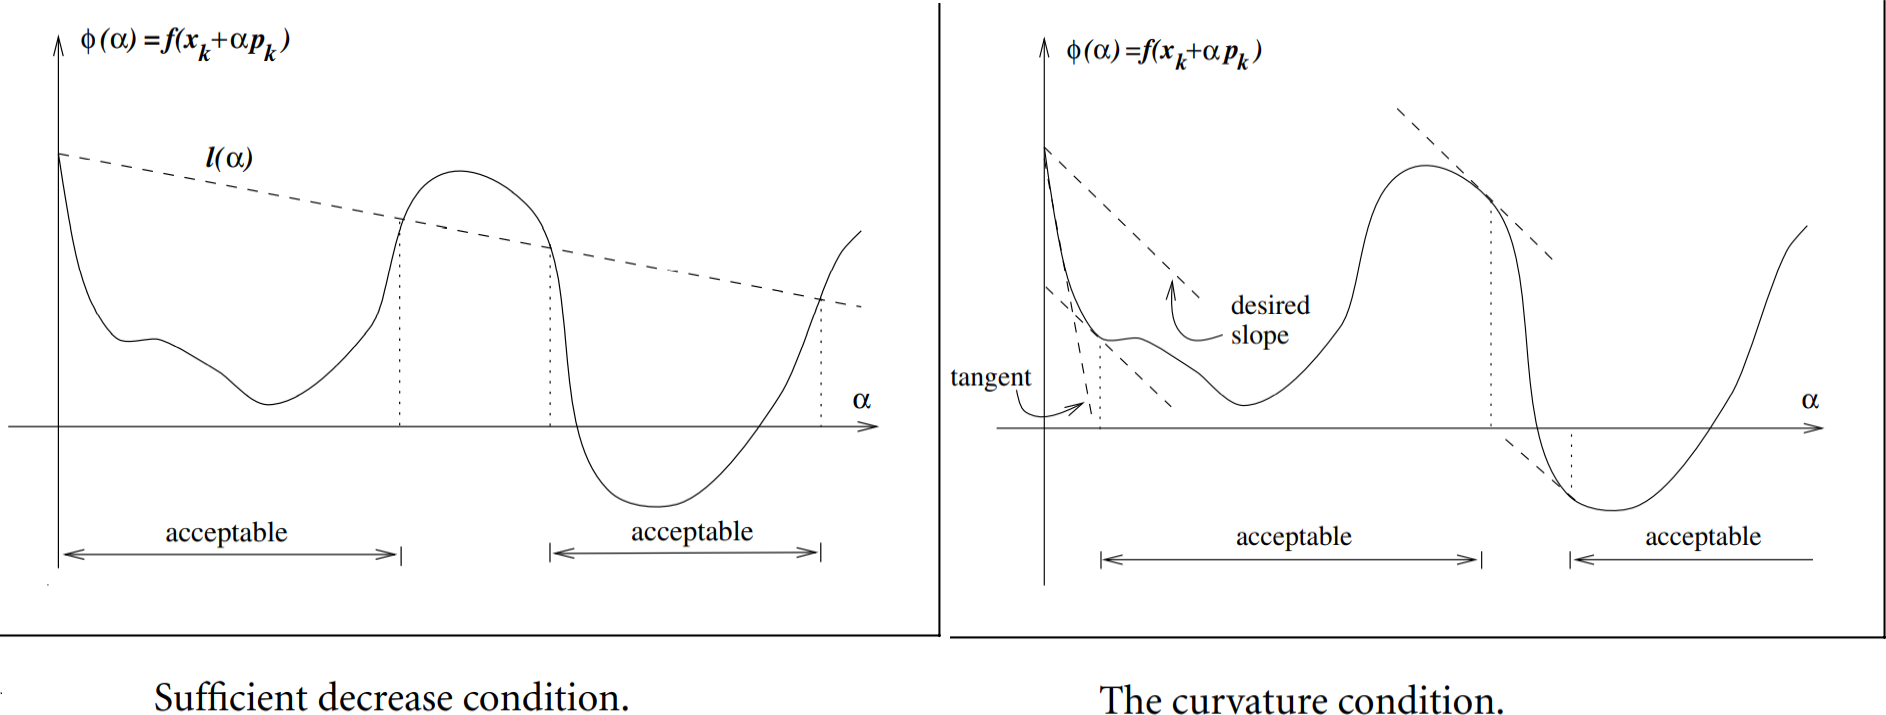

The **strong Wolfe conditions** require $\alpha _k$ to satisfy


$$f(x_k + \alpha p_k) \le  f(x_k) + c_1\alpha \nabla f(x_k)^T p_k$$
 


$$\left|\nabla f(x_k + \alpha p_k)^T p_k \right| \leq  c_2\left|\nabla f(x_k)^T p_k\right|$$


with $0<c_1 < c_2 <1$

**Question: I**s there a step size $\alpha$ that satisfies Wolfe Conditions? 

Yes for smooth $f$ that is bounded below. (Lemma)  

**Remark:** The Wolfe conditions are scale-invariant 

####     THE GOLDSTEIN CONDITIONS 

For $0< c< 1/2$,


$$f(x_k) + (1 - c)\alpha \nabla ^Tf_k p_k \le  f(x_k + \alpha p_k) \le  f(x_k) + c\alpha \nabla ^Tf_k p_k$$$


**SUFFICIENT DECREASE AND BACKTRACKING**

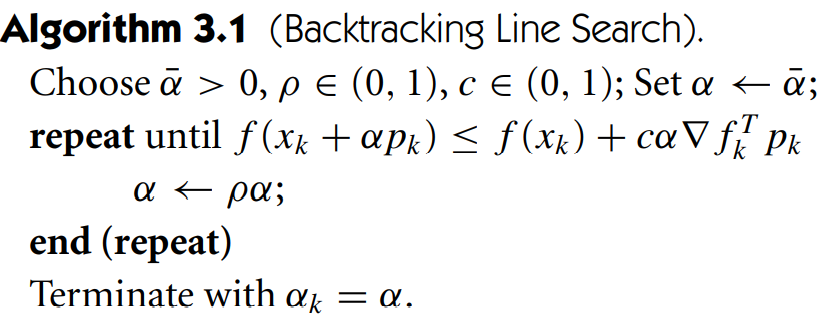

This simple and popular strategy for terminating a line search is well suited for Newton methods but is less appropriate for quasi-Newton and conjugate gradient methods.

## 3.2 CONVERGENCE OF LINE SEARCH METHODS

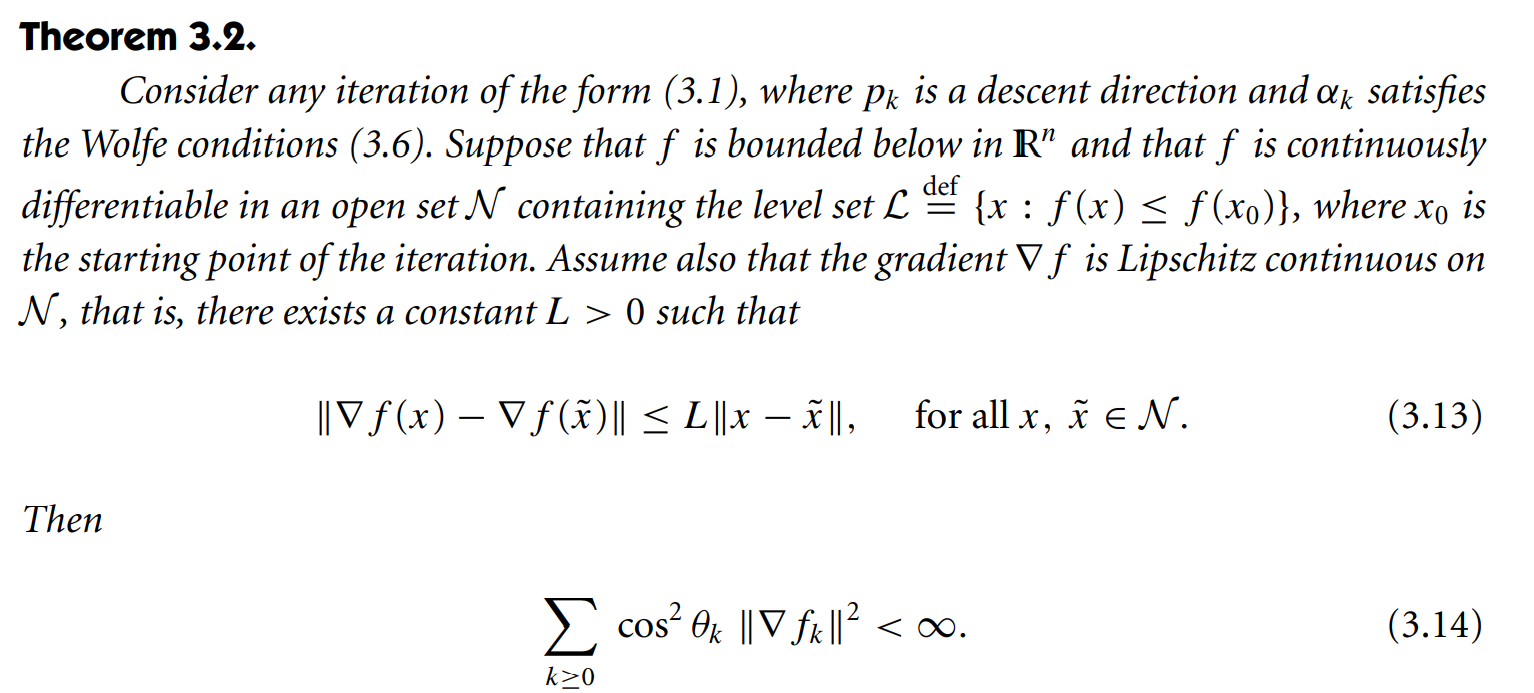

Here $\theta_k$ is the angle between $p_k$ and the steepest descent direction $-\nabla  f_k$ , defined by


$$\cos\theta_k = - \frac{\nabla^Tf_k p_k}{\|\nabla f_k\|\|p_k\|}$$


# Search Direction $p_k$


$$x_{k+1} =  x_k + \alpha _k p_k$$


- Steepest Descent: $p_k=-\nabla f_k$

- Newton Direction: $p_k=-H \nabla f_k$ where $H=\nabla^2f_k$ is the hessian matrix. $H>0$.

- Modified Newton’s methods: If $H$ is indefinite, ill-conditioned, or singular, the modified Newton’s methods compute the inverse of $H+E$, such that $-(H+E)^{-1}\nabla f _k$ gives a descent direction. 

## 3.4 NEWTON’S METHOD WITH HESSIAN MODIFICATION

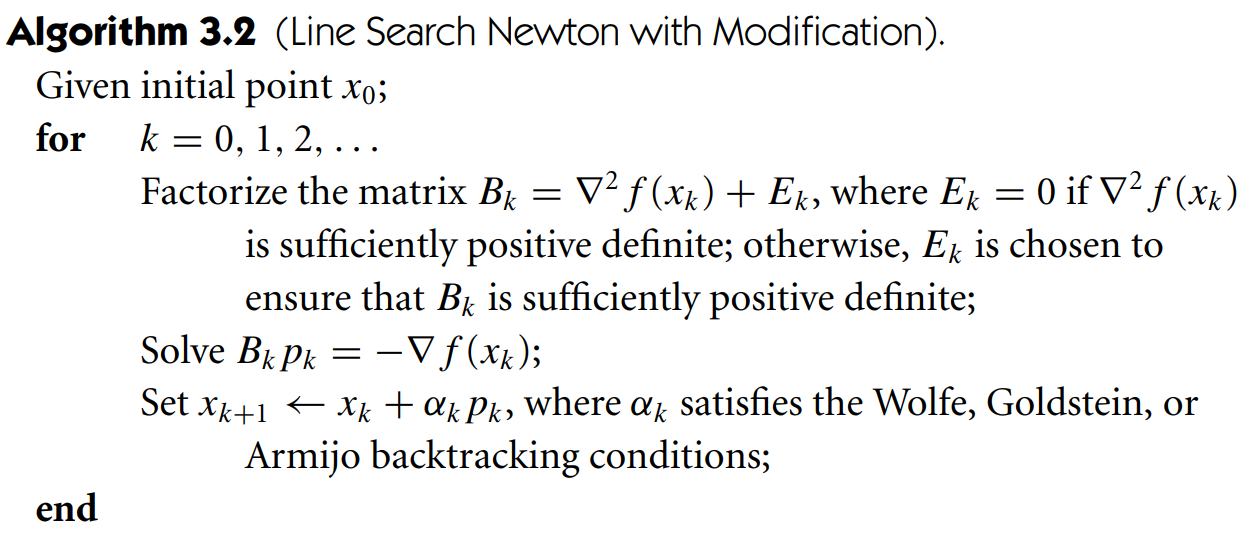

How to choose $E$? $E$ must satisfy the *bounded modified factorizatio;* that is

$\kappa(B_k) = \|B_k\|\|B_k^{-1}\|\leq C,$  for some $C>0$ and all $k$

Bk =[3     3     2; ...
    1     3     1; ...
    2     3     3];

 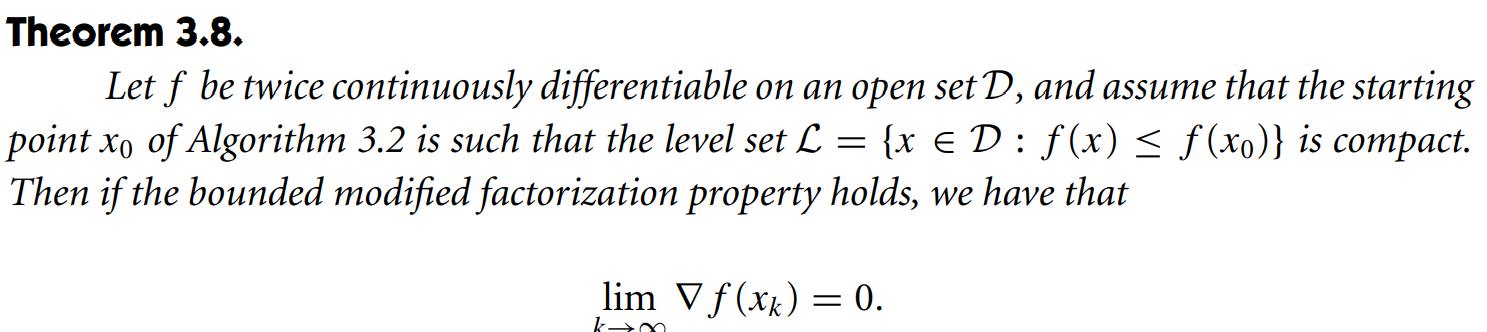

- EIGENVALUE MODIFICATION

- ADDING A MULTIPLE OF THE IDENTITY (Diagonal shift)

- MODIFIED CHOLESKY FACTORIZATION

- MODIFIED SYMMETRIC INDEFINITE FACTORIZATION

####     EIGENVALUE MODIFICATION

- Modifying the eigenvalues of $H$ such that $H$ becomes positive definite 

- Let $H=Q\Lambda Q^T$ be the spectral decomposition of $H$.  [Q,L]=eig(H)

- $\Lambda  = diag(\lambda _1, \lambda _2,\dots ,\lambda _n)$ where $\lambda _1\ge \dots \ge  \lambda _i>0\ge \lambda _{i+1}\ge \dots  \ge  \lambda _n$ 

- Define $∆\Lambda =diag(0,\dots ,0,∆\lambda _{i+1},\dots ,∆\lambda _n)$ s.t. $\Lambda +∆\Lambda  > 0$

- Matrix $E=Q∆\Lambda Q^T$ 

- Problem: the eigenvalue decomposition is too expensive.

####     ADDING A MULTIPLE OF THE IDENTITY (Diagonal shift)

- If $∆\Lambda =diag(\tau,\dots , \tau) = \tau I$, $E = Q∆\Lambda Q^T = \tau QQ^T =\tau I$

To make $H+E$ positive definite, only need to choose $\tau >|\lambda _i|$, where $\lambda _i$ is minimum negative eigenvalues of $H$.

How to know $\tau$ without explicitly performing the eigenvalue decomposition?    

- If H is positive definite, H has Cholesky decomposition. 

- Guess a shift $\tau$ and try Cholesky decomposition on $H+\tau I$. If fails, increase $\tau$ and try again, until success

- The choice of increment is heuristic.

####     MODIFIED CHOLESKY FACTORIZATION

- A symmetric positive definite (SPD) matrix H can be decomposed as $H=LDL^T$. 

- $L$ is unit triangular matrix 

- $D$ is diagonal with positive elements 

- Relations to Cholesky decomp $H=MM^T$ is $M=LD^{1/2}$

- If $A$ is not SPD, modify the elements of $L$ and $D$ during the decomposition such that: $D(i,i)\ge  \delta  > 0$ and $L(i,j)D(i,i)^{1/2} \le  \beta $.

- The decomposition can be used in solving linear systems.

####     MODIFIED SYMMETRIC INDEFINITE FACTORIZATION

- Symmetric indefinite factorization $PHP^T=LBL^T$: (1) better numerical stability than Cholesky decomposition (2) Matrix $B$ has the same inertia as $H$ (# positive, #negative, #zero eigenvalues) 

- Use eigenvalue modification to $B$ st. $B+F$ is positive definite: The eigen-decomp of $B$ is cheap since it is block diagonal

- Thus, $P(H+E)P^T=L(B+F)L^T$ and $E=P^TLFL^TP$ 

## 3.3 RATE OF CONVERGENCE

**Definition:**

A sequence ${\displaystyle (x_{n})}$ that converges to ${\displaystyle x^{*}}$ is said to have ***order of convergence*** ${\displaystyle q\geq 1}$ and ***rate of convergence*** ${\displaystyle \mu }$ if 


$${\displaystyle \lim _{n\rightarrow \infty }{\frac {\left|x_{n+1}-x^{*}\right|}{\left|x_{n}-x^{*}\right|^{q}}}=\mu .}$$


The value ${\displaystyle \mu }$ is also called the ***asymptotic error constant***.

If $q=1$, then

- if $\mu=1$, the convergence is **sublinear**.

- if $\mu \in (0,1)$, the convergence is **linear **with a rate $\mu$.

- if $\mu=0$, the convergence is **superlinear**.

If $q=2$, $\mu>0$, the convergence is **quadratic**.

If $q=3$, $\mu>0$, the convergence is **cubic**.

For definitions of rate of convergence, see this [source](http://fourier.eng.hmc.edu/e176/lectures/NM/node3.html)

####     CONVERGENCE RATE OF STEEPEST DESCENT

    

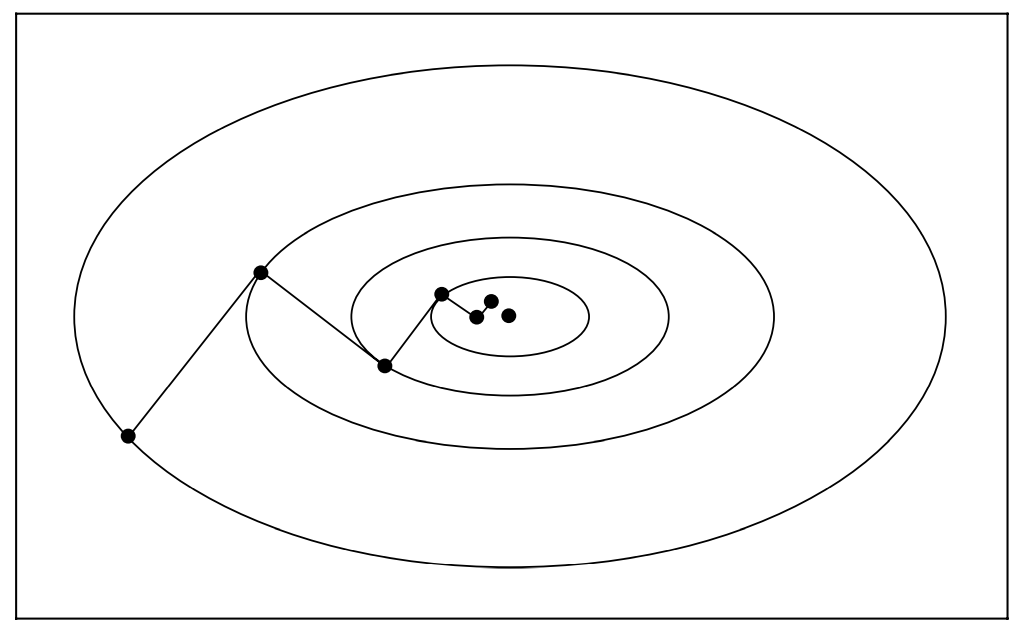 

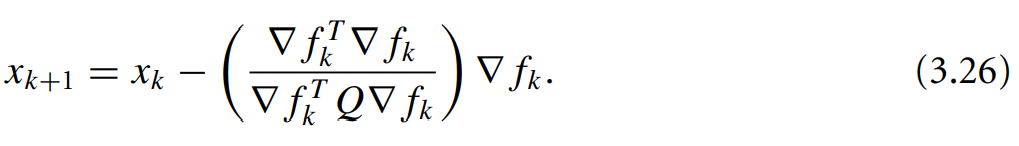

 here $\|x\|^2_Q=x^TQx$

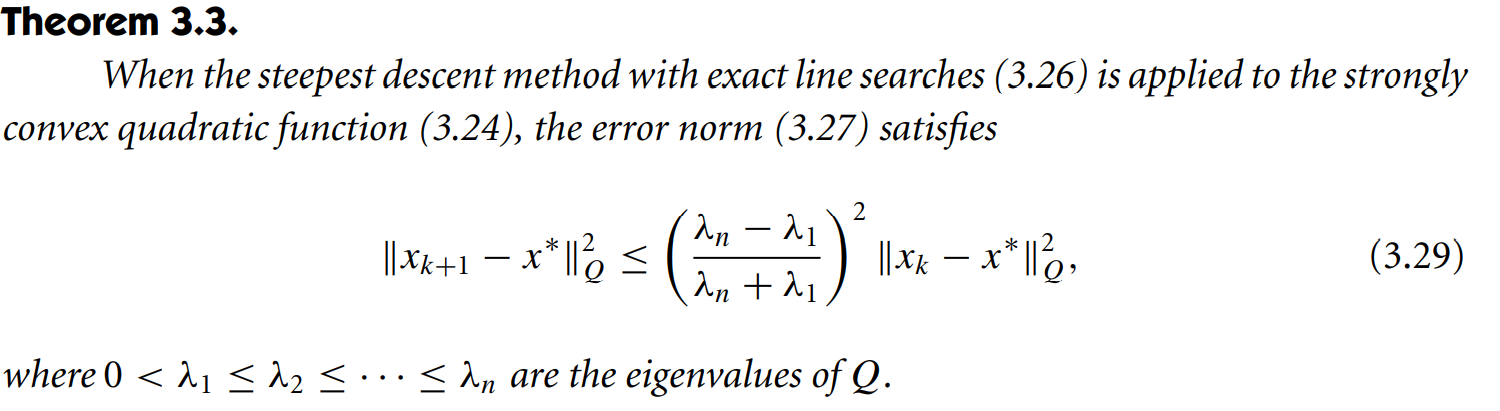

This shows that $f_k$ converges to $f^*$ at a *linear rate*.

In general Nonlinear Case

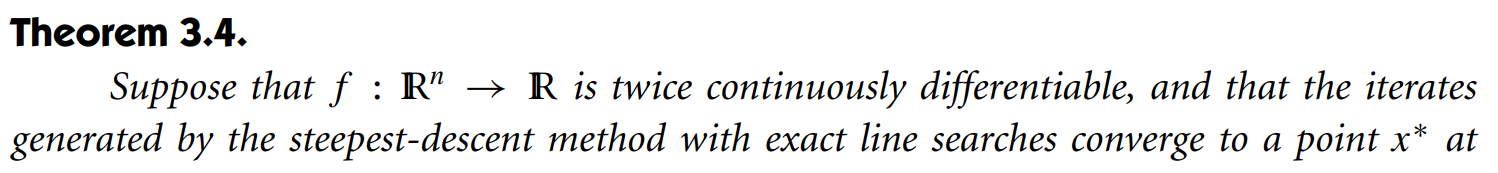

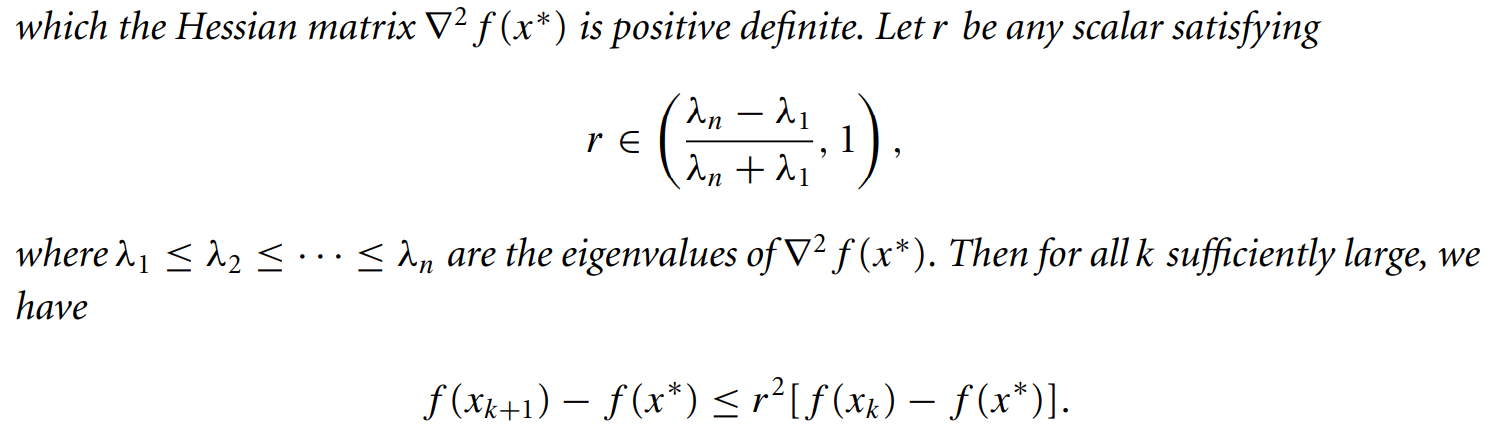

####     NEWTON’S METHOD

    The rate of convergence is **quadratic**

####     QUASI-NEWTON METHODS


$$p_k= -B^{-1}_k \nabla  f_k$$
 

    where the symmetric and positive definite matrix $B_k$ is updated at every iteration by a quasi-Newton updating formula.

    The rate of convergence is **superlinear**.

## 3.5 STEP-LENGTH SELECTION ALGORITHMS

    We are solving


$$\min_{\alpha >0} \phi(\alpha ) = f(x_k + \alpha p_k)$$


- All line search methods starts with a guess $\alpha_0$ and generates a sequence $\{\alpha_i\}$ which either terminates with a step size or shows no such step exists.

- Procedures to find a step size have two phases: (1) **bracketing** to find an interval $[\bar{a},\bar{b}]$. (2) selection (zoom) phase that finds the "best" step size.   

####     INTERPOLATION

####     INITIAL STEP LENGTH

- $\alpha_0=1$ for Newton and quasi-Newton methods.

- for steepest descent and conjugate gradient methods use current information about the problem and the algorithm to make the initial guess.

####     A LINE SEARCH ALGORITHM FOR THE WOLFE CONDITIONS